%% Setup and Configuration
clear; clc; close all;

% Add current directory to path
addpath(pwd);

% Check Python availability
[status, pyver] = system('python --version');
if status == 0
    fprintf('Python detected: %s\n', strtrim(pyver));
else
    warning('Python not found. Please ensure Python is on PATH.');
end

Python detected: Python 3.12.10



%% User Parameters - Image Generation
prompt = 'A scenic mountain landscape at sunset, photorealistic';
steps = 28;              % Diffusion steps
seed = 42;               % Random seed (for reproducibility)
model_id = 'stabilityai/stable-diffusion-2-1';
output_filename = 'generated.png';

%% Step 1: Generate Image with Python Diffusion Model
fprintf('\n=== STEP 1: Generating Image with Stable Diffusion ===\n');


=== STEP 1: Generating Image with Stable Diffusion ===



cmd = sprintf('python generate_image.py --prompt "%s" --steps %d --seed %d --model "%s" --out "%s"', ...
    prompt, steps, seed, model_id, output_filename);

fprintf('Running: %s\n\n', cmd);

Running: python generate_image.py --prompt "A scenic mountain landscape at sunset, photorealistic" --steps 28 --seed 42 --model "stabilityai/stable-diffusion-2-1" --out "generated.png"



[status, cmdout] = system(cmd);

if status ~= 0
    fprintf('Warning: Generator returned status %d\n', status);
end
fprintf('%s\n', cmdout);

Couldn't connect to the Hub: 404 Client Error. (Request ID: Root=1-696907eb-21aed6a26d10ef171eb76a8c;ff4e00b8-8bd1-41cd-8ecb-1307cc7a76b3)

Repository Not Found for url: https://huggingface.co/api/models/stabilityai/stable-diffusion-2-1.
Please make sure you specified the correct `repo_id` and `repo_type`.
If you are trying to access a private or gated repo, make sure you are authenticated. For more details, see https://huggingface.co/docs/huggingface_hub/authentication.
Will try to load from local cache.
Attempting fallback model runwayml/stable-diffusion-v1-5...
Loading pipeline components...:   0%|          | 0/7 [00:00<?, ?it/s]`torch_dtype` is deprecated! 

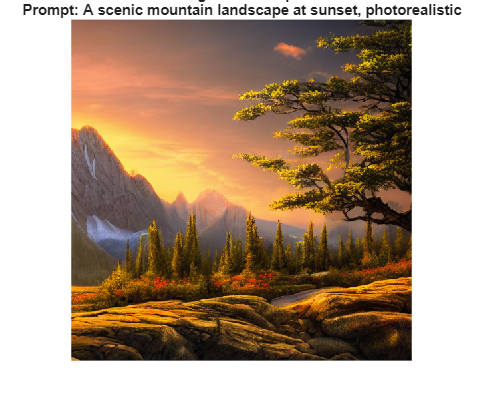


% Verify generated image exists
if ~exist(output_filename, 'file')
    error('Generated image not found: %s', output_filename);
end

% Load and display original
img_original = imread(output_filename);
figure('Name', 'Original Generated Image', 'Color', 'w', 'Position', [100 100 800 600]);
imshow(img_original);
title(sprintf('Original SD Output\nPrompt: %s', prompt), 'Interpreter', 'none');



% Frequency domain parameters
params = struct();
params.freq_threshold = 16;      % LF/HF cutoff radius (in frequency bins)
params.transition_width = 6;     % Smooth transition between LF/HF

% Backbone scaling factors (Fm in paper equations 13-14)
params.backbone_hf_scale = 1.3;        % θmh: High frequency scaling
params.backbone_lf_scale = 0.6;        % θml: Low frequency scaling
params.backbone_hf_amp_scale = 1.2;    % amh: HF amplitude scaling
params.backbone_lf_amp_scale = 0.5;    % aml: LF amplitude scaling
params.backbone_hf_phase_scale = 1.0;  % pmh: HF phase scaling (paper: minimal effect)
params.backbone_lf_phase_scale = 0.4;  % pml: LF phase scaling

% Skip connection scaling factors (Fn in paper equations 13-14)
params.skip_hf_scale = 1.3;            % θnh: High frequency scaling
params.skip_lf_scale = 0.4;            % θnl: Low frequency scaling
params.skip_hf_amp_scale = 1.3;        % anh: HF amplitude scaling
params.skip_lf_amp_scale = 0.6;        % anl: LF amplitude scaling
params.skip_hf_phase_scale = 0.7;      % pnh: HF phase scaling
params.skip_lf_phase_scale = 1.4;      % pnl: LF phase scaling

% Global parameters
params.global_scale = 1.0;       % Overall intensity scaling
params.blend_alpha = 0.95;       % Blend between original and enhanced [0-1]

% Processing mode
params.mode = 'full_dmfft';      % Options: 'full_dmfft', 'backbone_only', 'skip_only'

%% Step 2: Apply DMFFT Processing
fprintf('\n=== STEP 2: Applying DMFFT Frequency Domain Enhancement ===\n');


=== STEP 2: Applying DMFFT Frequency Domain Enhancement ===



% Process each channel separately (RGB)
img_double = im2double(img_original);
[H, W, C] = size(img_double);

if C == 1
    img_double = repmat(img_double, [1, 1, 3]);
    C = 3;
end

% Convert to YCbCr for better color preservation
img_ycbcr = rgb2ycbcr(img_double);
Y_channel = img_ycbcr(:,:,1);
Cb_channel = img_ycbcr(:,:,2);
Cr_channel = img_ycbcr(:,:,3);

% Create frequency-domain masks (centered coordinates)
[lf_mask, hf_mask] = create_frequency_masks(H, W, params.freq_threshold, params.transition_width);

%% DMFFT Processing - Backbone Branch (Simulated)
% In true DMFFT, this happens inside U-Net during sampling
% Here we demonstrate the frequency manipulation on the final image

fprintf('Processing backbone features (simulated)...\n');

Processing backbone features (simulated)...



% FFT of luminance channel
Y_freq = fftshift(fft2(Y_channel * params.global_scale));

% Separate LF and HF components (Equation 11-12 in paper)
Y_lf_freq = Y_freq .* lf_mask;
Y_hf_freq = Y_freq .* hf_mask;

% Extract amplitude and phase for LF
Y_lf_amp = abs(Y_lf_freq);
Y_lf_phase = angle(Y_lf_freq);

% Extract amplitude and phase for HF
Y_hf_amp = abs(Y_hf_freq);
Y_hf_phase = angle(Y_hf_freq);

% Apply backbone scaling (Equation 13 in paper)
% F_m' = b × IFFT(F_ham × amh + F_lam × aml + F_hpm × pmh + F_lpm × pml)

backbone_lf_amp_scaled = Y_lf_amp * params.backbone_lf_amp_scale;
backbone_lf_phase_scaled = Y_lf_phase * params.backbone_lf_phase_scale;
backbone_hf_amp_scaled = Y_hf_amp * params.backbone_hf_amp_scale;
backbone_hf_phase_scaled = Y_hf_phase * params.backbone_hf_phase_scale;

% Reconstruct complex frequency components
backbone_lf_freq = backbone_lf_amp_scaled .* exp(1i * backbone_lf_phase_scaled);
backbone_hf_freq = backbone_hf_amp_scaled .* exp(1i * backbone_hf_phase_scaled);

% Apply frequency scaling
backbone_lf_freq = backbone_lf_freq * params.backbone_lf_scale;
backbone_hf_freq = backbone_hf_freq * params.backbone_hf_scale;

% Combine and inverse FFT
Y_backbone = real(ifft2(ifftshift(backbone_lf_freq + backbone_hf_freq)));

%% DMFFT Processing - Skip Connection Branch (Simulated)
fprintf('Processing skip connection features (simulated)...\n');

Processing skip connection features (simulated)...



% Skip connections process the same image with different parameters
% Apply skip scaling (Equation 14 in paper)

skip_lf_amp_scaled = Y_lf_amp * params.skip_lf_amp_scale;
skip_lf_phase_scaled = Y_lf_phase * params.skip_lf_phase_scale;
skip_hf_amp_scaled = Y_hf_amp * params.skip_hf_amp_scale;
skip_hf_phase_scaled = Y_hf_phase * params.skip_hf_phase_scale;

% Reconstruct complex frequency components
skip_lf_freq = skip_lf_amp_scaled .* exp(1i * skip_lf_phase_scaled);
skip_hf_freq = skip_hf_amp_scaled .* exp(1i * skip_hf_phase_scaled);

% Apply frequency scaling
skip_lf_freq = skip_lf_freq * params.skip_lf_scale;
skip_hf_freq = skip_hf_freq * params.skip_hf_scale;

% Combine and inverse FFT
Y_skip = real(ifft2(ifftshift(skip_lf_freq + skip_hf_freq)));

%% Combine Backbone and Skip (Feature Fusion)
fprintf('Fusing backbone and skip features...\n');

Fusing backbone and skip features...



% In U-Net, backbone and skip are concatenated: [backbone, skip]
% Here we average them for demonstration
switch params.mode
    case 'backbone_only'
        Y_enhanced = Y_backbone;
    case 'skip_only'
        Y_enhanced = Y_skip;
    case 'full_dmfft'
        Y_enhanced = (Y_backbone + Y_skip) / 2;
end

% Normalize to preserve mean and variance (gentle normalization)
Y_enhanced = Y_enhanced - mean(Y_enhanced(:));
Y_enhanced = Y_enhanced * (std(Y_channel(:)) / (std(Y_enhanced(:)) + eps));
Y_enhanced = Y_enhanced + mean(Y_channel(:));

% Blend with original
Y_final = params.blend_alpha * Y_enhanced + (1 - params.blend_alpha) * Y_channel;

% Reassemble YCbCr
img_enhanced_ycbcr = cat(3, Y_final, Cb_channel, Cr_channel);
img_enhanced = ycbcr2rgb(img_enhanced_ycbcr);

% Clip values
img_enhanced = min(max(img_enhanced, 0), 1);

% Save enhanced image
imwrite(img_enhanced, 'dmfft_enhanced.png');
fprintf('Enhanced image saved: dmfft_enhanced.png\n');

Enhanced image saved: dmfft_enhanced.png



%% Step 3: Visualization and Analysis
fprintf('\n=== STEP 3: Visualization and Analysis ===\n');


=== STEP 3: Visualization and Analysis ===


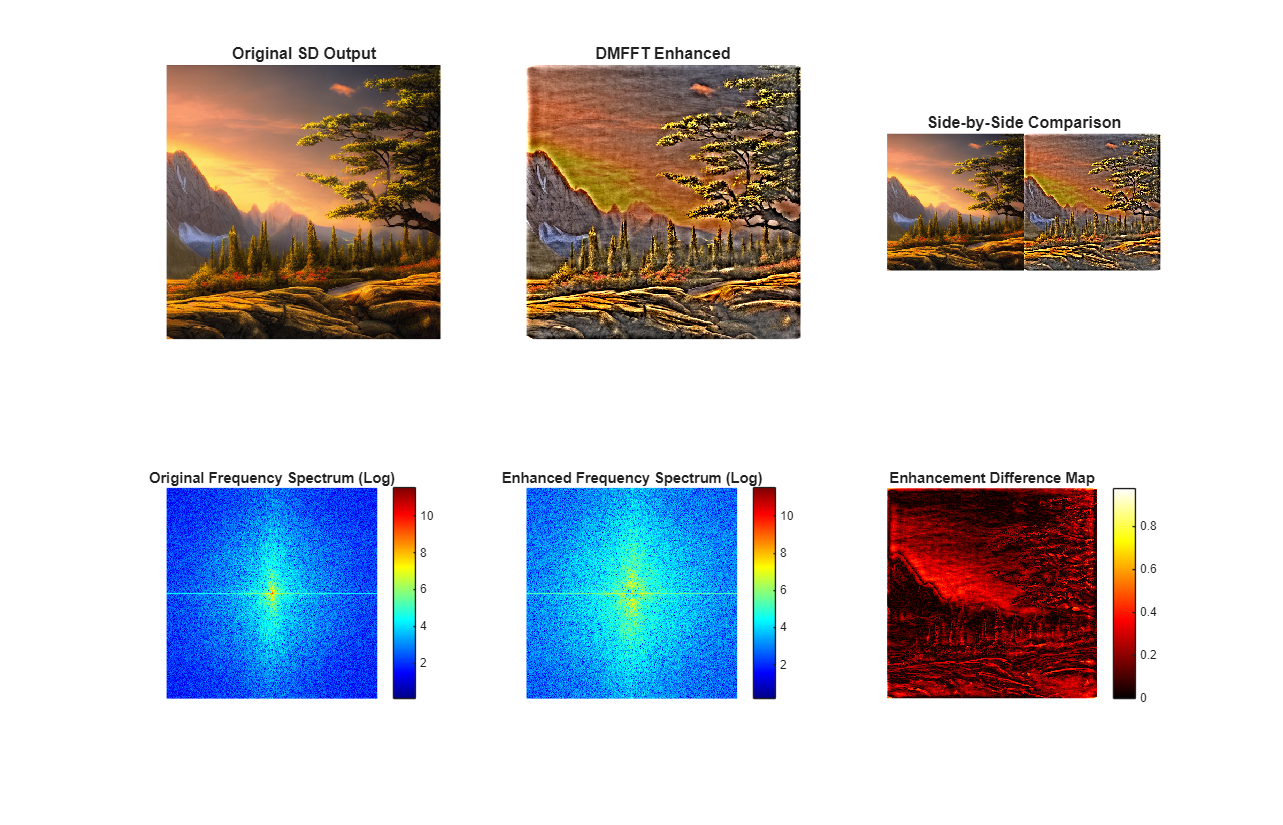


% Create comprehensive visualization
figure('Name', 'DMFFT Analysis', 'Color', 'w', 'Position', [100 100 1400 900]);

% Original vs Enhanced
subplot(2,3,1);
imshow(img_double);
title('Original SD Output', 'FontSize', 12, 'FontWeight', 'bold');

subplot(2,3,2);
imshow(img_enhanced);
title('DMFFT Enhanced', 'FontSize', 12, 'FontWeight', 'bold');

subplot(2,3,3);
imshowpair(img_double, img_enhanced, 'montage');
title('Side-by-Side Comparison', 'FontSize', 12, 'FontWeight', 'bold');

% Frequency domain visualization
subplot(2,3,4);
imagesc(log(abs(Y_freq) + 1));
axis image; axis off; colormap(gca, 'jet'); colorbar;
title('Original Frequency Spectrum (Log)', 'FontSize', 11);

subplot(2,3,5);
Y_enhanced_freq = fftshift(fft2(Y_final));
imagesc(log(abs(Y_enhanced_freq) + 1));
axis image; axis off; colormap(gca, 'jet'); colorbar;
title('Enhanced Frequency Spectrum (Log)', 'FontSize', 11);

% Difference map
subplot(2,3,6);
diff_img = abs(img_enhanced - img_double);
imagesc(mean(diff_img, 3));
axis image; axis off; colormap(gca, 'hot'); colorbar;
title('Enhancement Difference Map', 'FontSize', 11);


%% Step 4: Ablation Study - Individual Component Analysis
fprintf('\n=== STEP 4: Ablation Study - Analyzing Individual Components ===\n');


=== STEP 4: Ablation Study - Analyzing Individual Components ===


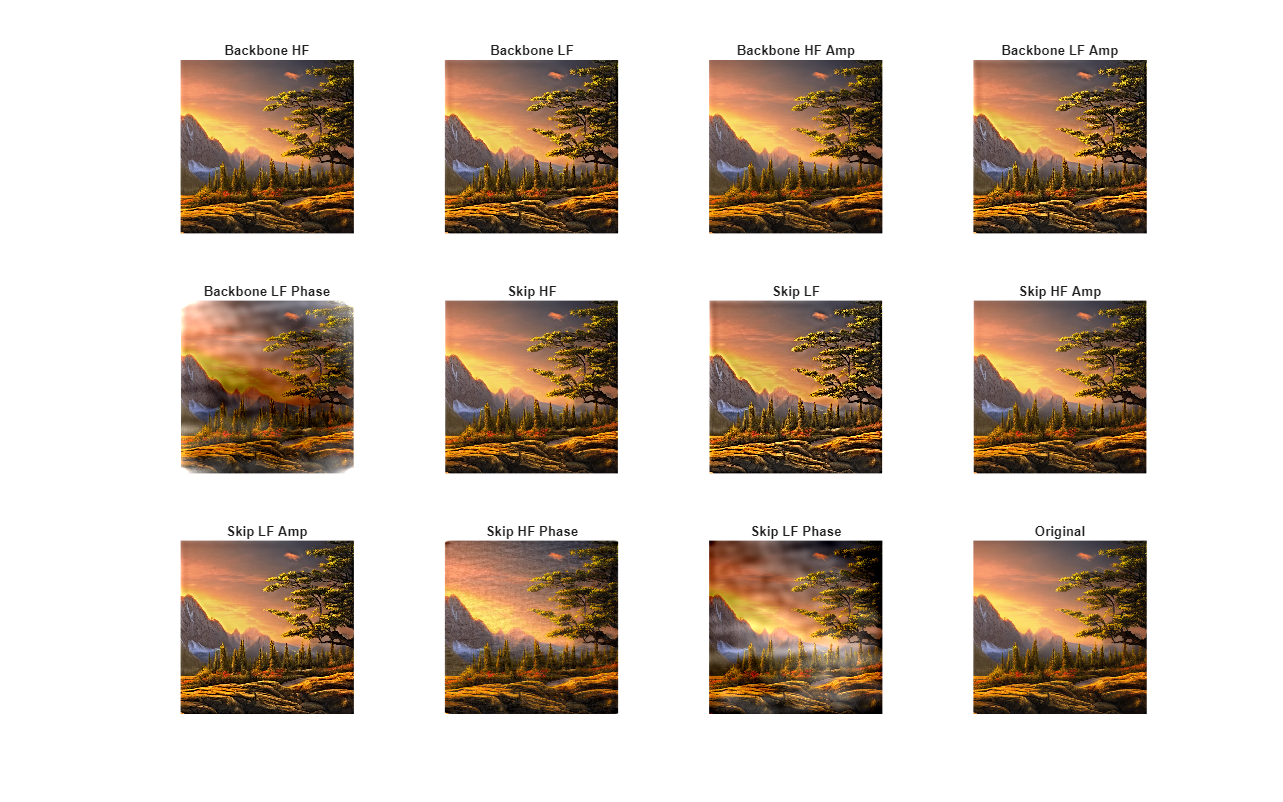


% Test each frequency component individually (as shown in Fig. 25 of paper)
components = {
    'backbone_hf', 'Backbone HF', [1.3, 1.0, 1.0, 1.0, 1.0, 1.0];
    'backbone_lf', 'Backbone LF', [1.0, 0.6, 1.0, 1.0, 1.0, 1.0];
    'backbone_hf_amp', 'Backbone HF Amp', [1.0, 1.0, 1.2, 1.0, 1.0, 1.0];
    'backbone_lf_amp', 'Backbone LF Amp', [1.0, 1.0, 1.0, 0.5, 1.0, 1.0];
    'backbone_lf_phase', 'Backbone LF Phase', [1.0, 1.0, 1.0, 1.0, 1.0, 0.4];
    'skip_hf', 'Skip HF', [1.3, 1.0, 1.0, 1.0, 1.0, 1.0];
    'skip_lf', 'Skip LF', [1.0, 0.4, 1.0, 1.0, 1.0, 1.0];
    'skip_hf_amp', 'Skip HF Amp', [1.0, 1.0, 1.3, 1.0, 1.0, 1.0];
    'skip_lf_amp', 'Skip LF Amp', [1.0, 1.0, 1.0, 0.6, 1.0, 1.0];
    'skip_hf_phase', 'Skip HF Phase', [1.0, 1.0, 1.0, 1.0, 0.7, 1.0];
    'skip_lf_phase', 'Skip LF Phase', [1.0, 1.0, 1.0, 1.0, 1.0, 1.4];
};

figure('Name', 'DMFFT Ablation Study', 'Color', 'w', 'Position', [50 50 1600 1000]);

for i = 1:size(components, 1)
    component_name = components{i, 1};
    component_label = components{i, 2};
    scales = components{i, 3};
    
    % Apply single component scaling
    test_params = params;
    
    if contains(component_name, 'backbone')
        test_params.backbone_hf_scale = scales(1);
        test_params.backbone_lf_scale = scales(2);
        test_params.backbone_hf_amp_scale = scales(3);
        test_params.backbone_lf_amp_scale = scales(4);
        test_params.backbone_hf_phase_scale = scales(5);
        test_params.backbone_lf_phase_scale = scales(6);
        test_params.mode = 'backbone_only';
    else
        test_params.skip_hf_scale = scales(1);
        test_params.skip_lf_scale = scales(2);
        test_params.skip_hf_amp_scale = scales(3);
        test_params.skip_lf_amp_scale = scales(4);
        test_params.skip_hf_phase_scale = scales(5);
        test_params.skip_lf_phase_scale = scales(6);
        test_params.mode = 'skip_only';
    end
    
    % Process with single component
    img_component = apply_dmfft_single(Y_channel, Cb_channel, Cr_channel, ...
        lf_mask, hf_mask, test_params);
    
    % Display
    subplot(3, 4, i);
    imshow(img_component);
    title(component_label, 'FontSize', 10, 'FontWeight', 'bold');
end

% Original image in last position
subplot(3, 4, 12);
imshow(img_double);
title('Original', 'FontSize', 10, 'FontWeight', 'bold');


%% Step 5: Parameter Sweep Analysis
fprintf('\n=== STEP 5: Parameter Sweep - Analyzing Value Ranges ===\n');


=== STEP 5: Parameter Sweep - Analyzing Value Ranges ===


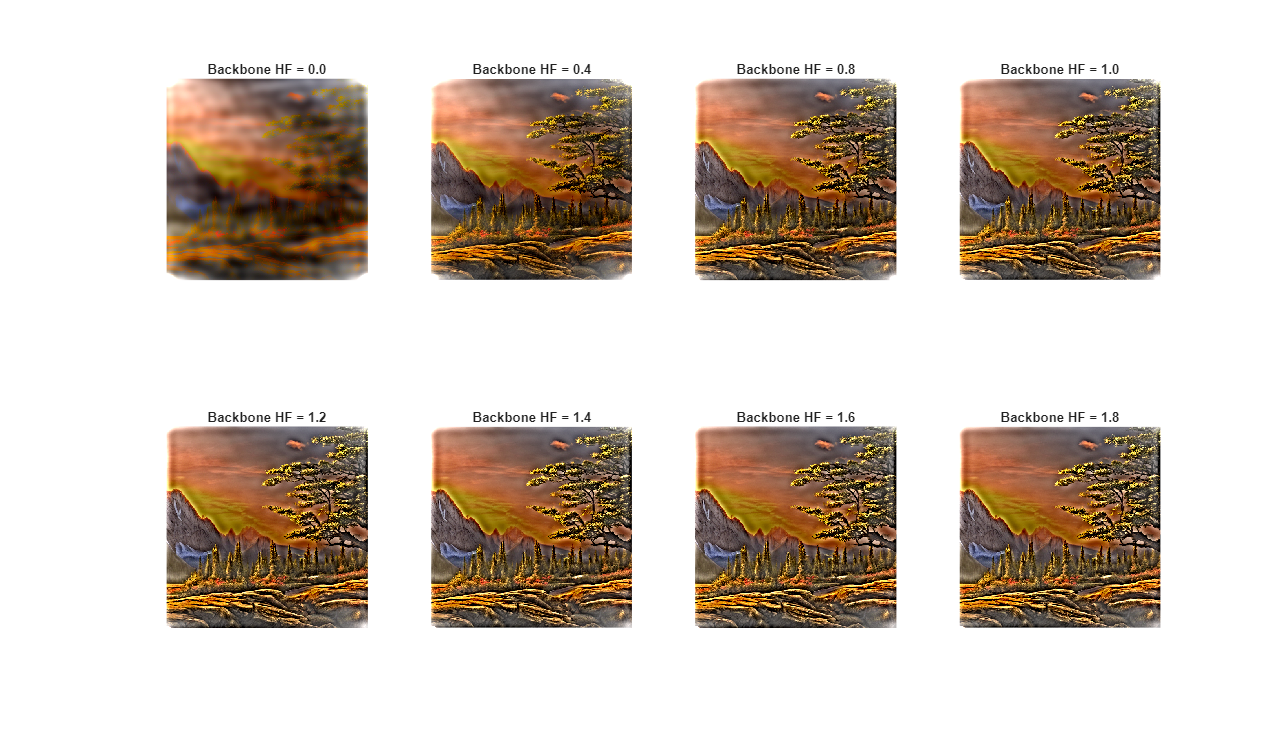


% Sweep backbone HF scale (as shown in Fig. 7 of paper)
test_values = [0.0, 0.4, 0.8, 1.0, 1.2, 1.4, 1.6, 1.8];

figure('Name', 'Backbone HF Scaling Sweep', 'Color', 'w', 'Position', [100 100 1400 800]);

for i = 1:length(test_values)
    test_params = params;
    test_params.backbone_hf_scale = test_values(i);
    test_params.mode = 'backbone_only';
    
    img_test = apply_dmfft_single(Y_channel, Cb_channel, Cr_channel, ...
        lf_mask, hf_mask, test_params);
    
    subplot(2, 4, i);
    imshow(img_test);
    title(sprintf('Backbone HF = %.1f', test_values(i)), 'FontSize', 10);
end


%% Summary Statistics
fprintf('\n=== SUMMARY ===\n');


=== SUMMARY ===


fprintf('Original image size: %d x %d\n', H, W);

Original image size: 512 x 512


fprintf('Frequency threshold: %d bins\n', params.freq_threshold);

Frequency threshold: 16 bins


fprintf('LF mask coverage: %.2f%%\n', 100*sum(lf_mask(:))/(H*W));

LF mask coverage: 0.31%


fprintf('HF mask coverage: %.2f%%\n', 100*sum(hf_mask(:))/(H*W));

HF mask coverage: 99.69%



% Quality metrics
mse = mean((img_enhanced(:) - img_double(:)).^2);
psnr_value = 10*log10(1/mse);
fprintf('PSNR: %.2f dB\n', psnr_value);

PSNR: 15.14 dB



fprintf('\nDMFFT processing complete!\n');


DMFFT processing complete!


fprintf('Files generated:\n');

Files generated:


fprintf('  - %s (original from SD)\n', output_filename);

  - generated.png (original from SD)


fprintf('  - dmfft_enhanced.png (DMFFT result)\n');

  - dmfft_enhanced.png (DMFFT result)



%% Helper Functions

function [lf_mask, hf_mask] = create_frequency_masks(H, W, threshold, transition_width)
    % Create smooth LF/HF masks in frequency domain (as in paper)
    % Uses centered frequency coordinates
    
    uIdx = (-floor(H/2)):(ceil(H/2)-1);
    vIdx = (-floor(W/2)):(ceil(W/2)-1);
    [U, V] = ndgrid(uIdx, vIdx);
    freq_dist = sqrt(double(U).^2 + double(V).^2);
    
    % Smooth transition mask
    lf_mask = zeros(H, W);
    inner = freq_dist <= (threshold - transition_width);
    outer = freq_dist >= (threshold + transition_width);
    trans = ~inner & ~outer;
    
    lf_mask(inner) = 1;
    % Cosine taper on transition band
    lf_mask(trans) = 0.5 * (1 + cos(pi * (freq_dist(trans) - (threshold - transition_width)) / (2*transition_width)));
    lf_mask(outer) = 0;
    
    hf_mask = 1 - lf_mask;
end

function img_out = apply_dmfft_single(Y_channel, Cb_channel, Cr_channel, lf_mask, hf_mask, params)
    % Apply DMFFT with given parameters
    
    Y_freq = fftshift(fft2(Y_channel * params.global_scale));
    
    Y_lf_freq = Y_freq .* lf_mask;
    Y_hf_freq = Y_freq .* hf_mask;
    
    Y_lf_amp = abs(Y_lf_freq);
    Y_lf_phase = angle(Y_lf_freq);
    Y_hf_amp = abs(Y_hf_freq);
    Y_hf_phase = angle(Y_hf_freq);
    
    switch params.mode
        case 'backbone_only'
            lf_amp_scaled = Y_lf_amp * params.backbone_lf_amp_scale;
            lf_phase_scaled = Y_lf_phase * params.backbone_lf_phase_scale;
            hf_amp_scaled = Y_hf_amp * params.backbone_hf_amp_scale;
            hf_phase_scaled = Y_hf_phase * params.backbone_hf_phase_scale;
            
            lf_freq_scaled = lf_amp_scaled .* exp(1i * lf_phase_scaled) * params.backbone_lf_scale;
            hf_freq_scaled = hf_amp_scaled .* exp(1i * hf_phase_scaled) * params.backbone_hf_scale;
            
        case 'skip_only'
            lf_amp_scaled = Y_lf_amp * params.skip_lf_amp_scale;
            lf_phase_scaled = Y_lf_phase * params.skip_lf_phase_scale;
            hf_amp_scaled = Y_hf_amp * params.skip_hf_amp_scale;
            hf_phase_scaled = Y_hf_phase * params.skip_hf_phase_scale;
            
            lf_freq_scaled = lf_amp_scaled .* exp(1i * lf_phase_scaled) * params.skip_lf_scale;
            hf_freq_scaled = hf_amp_scaled .* exp(1i * hf_phase_scaled) * params.skip_hf_scale;
    end
    
    Y_processed = real(ifft2(ifftshift(lf_freq_scaled + hf_freq_scaled)));
    
    % Normalize
    Y_processed = Y_processed - mean(Y_processed(:));
    Y_processed = Y_processed * (std(Y_channel(:)) / (std(Y_processed(:)) + eps));
    Y_processed = Y_processed + mean(Y_channel(:));
    
    % Blend
    Y_final = params.blend_alpha * Y_processed + (1 - params.blend_alpha) * Y_channel;
    
    % Reassemble
    img_ycbcr = cat(3, Y_final, Cb_channel, Cr_channel);
    img_out = ycbcr2rgb(img_ycbcr);
    img_out = min(max(img_out, 0), 1);
end